%Resnet 50 base code
%all networks were adjusted to work with this code
%different networks had different sizes which were indicated in the deep
%network designer
%
sz=224;
path="D:\git\FYP\Python\TwoStage\data\Pandora7k";
Genres=imageDatastore(path,"IncludeSubfolders",true)

Genres =   ImageDatastore with properties:

                       Files: {
                              ' ...\Pandora7k\Abstract_Expressionism\08d1dc50eee1b53179cf65936a064931.png';
                              ' ...\TwoStage\data\Pandora7k\Abstract_Expressionism\1021092_Hans_1.png';
                              ' ...\20100127_arshile_gorky_scent_of_apricots_in_fields.png'
                               ... and 7692 more
                              }
                     Folders: {
                              'D:\git\FYP\Python\TwoStage\data\Pandora7k'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


resizedGenres=augmentedImageDatastore([sz sz], Genres, 'ColorPreprocessing', 'gray2rgb')

resizedGenres =   augmentedImageDatastore with properties:

             NumObservations: 7695
                       Files: {7695×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


net=resnet50

net =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}


preds=classify(net, resizedGenres)

preds = 7695×1 categorical array
     wall clock 
     bubble 
     handkerchief 
     candle 
     book jacket 
     comic book 
     pencil sharpener 
     wall clock 
     wall clock 
     handkerchief 
     church 
     mailbag 
     comic book 
     handkerchief 
     pencil sharpener 
     wall clock 
     comic book 
     comic book 
     book jacket 
     butcher shop 
     coral fungus 
     book jacket 
     comic book 
     comic book 
     submarine 
     book jacket 
     castle 
     book jacket 
     jack-o'-lantern 
     book jacket 


Labelling

%Labeling
GenreLabel=imageDatastore(path, IncludeSubfolders=true, LabelSource="foldernames")

GenreLabel =   ImageDatastore with properties:

                       Files: {
                              ' ...\Pandora7k\Abstract_Expressionism\08d1dc50eee1b53179cf65936a064931.png';
                              ' ...\TwoStage\data\Pandora7k\Abstract_Expressionism\1021092_Hans_1.png';
                              ' ...\20100127_arshile_gorky_scent_of_apricots_in_fields.png'
                               ... and 7692 more
                              }
                     Folders: {
                              'D:\git\FYP\Python\TwoStage\data\Pandora7k'
                              }
                      Labels: [Abstract_Expressionism; Abstract_Expressionism; Abstract_Expressionism ... and 7692 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "p

%GenreNames=GenreLabel.Labels

S

% Different datasplits were testing using resnet50
% First split: 60% training, 40% remaining (which will be split into validation and test)
[genreTrain, genreRemaining] = splitEachLabel(GenreLabel, 0.6, 'randomized');

% Second split: 50% of the remaining 40% for validation, 50% for testing
[genreValidate, genreTest] = splitEachLabel(genreRemaining, 0.5, 'randomized');

% Check the number of images in each set
disp(['Training set: ' num2str(numel(genreTrain.Files))]);

Training set: 4615


disp(['Validation set: ' num2str(numel(genreValidate.Files))]);

Validation set: 1542


disp(['Test set: ' num2str(numel(genreTest.Files))]);

Test set: 1538


Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |       10.16% |       11.74% |       2.6999 |       2.6204 |          0.0100 |
|       1 |           5 |       00:00:19 |       33.59% |              |       1.8723 |              |          0.0100 |
|       1 |          10 |       00:00:30 |       47.66% |              |       1.5665 |              |          0.0100 |
|       1 |          15 |       00:00:40 |       50.00% |              |       1.2512 |   

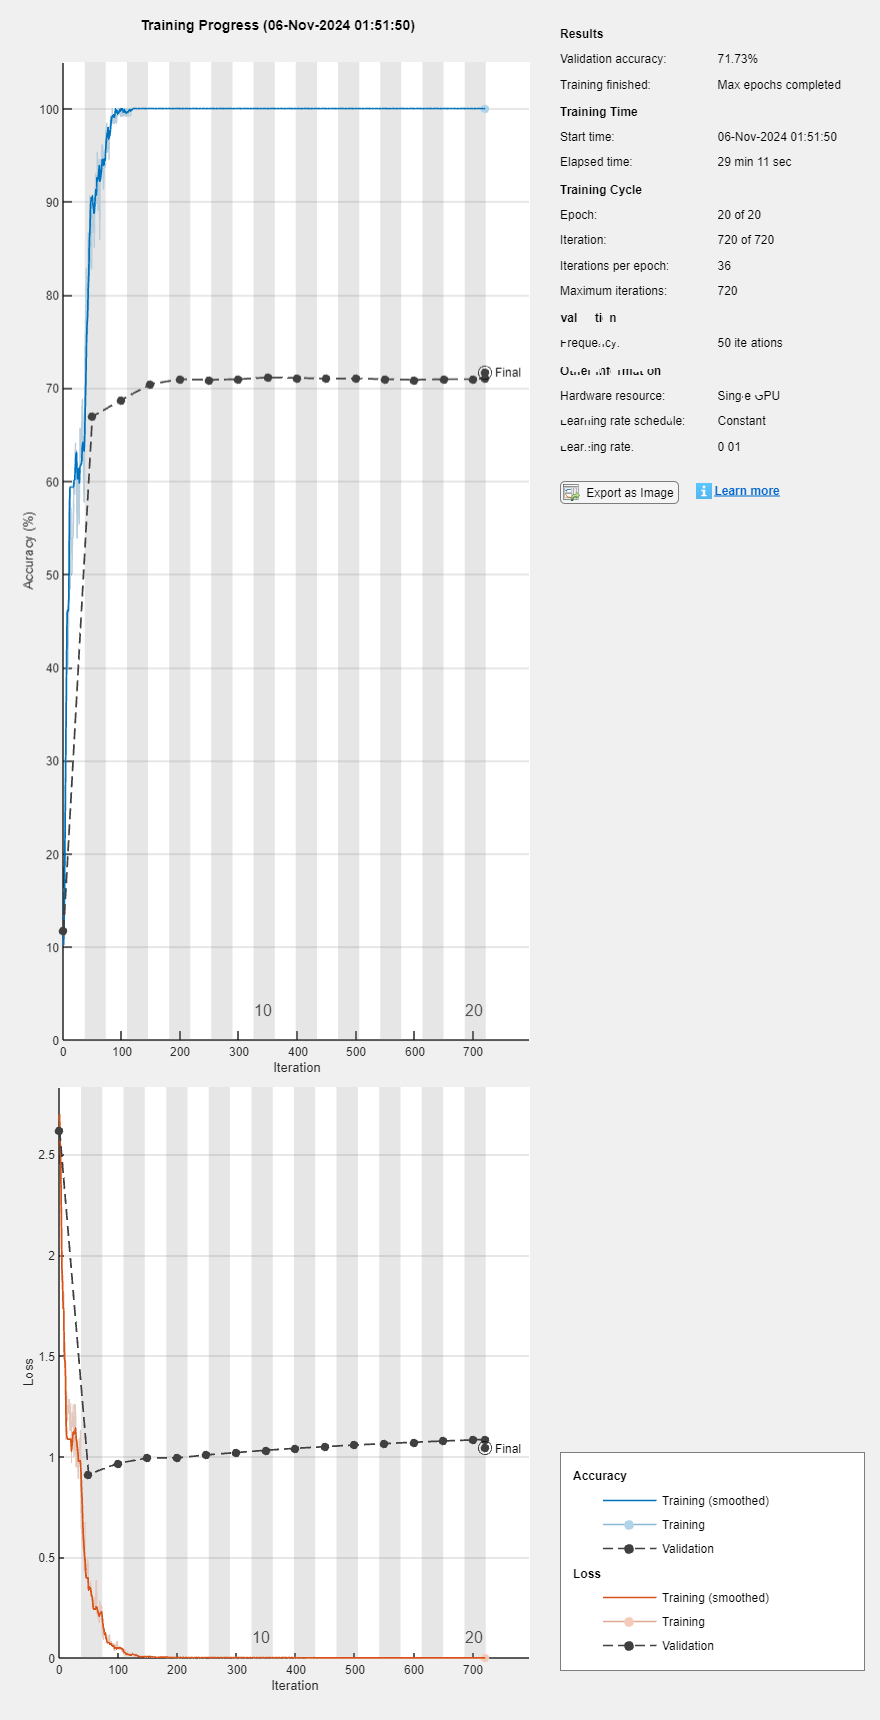



% Create augmentedImageDatastore for each set
resizeTrainImgs = augmentedImageDatastore([sz sz], genreTrain, 'ColorPreprocessing', 'gray2rgb');
resizeValidateImgs = augmentedImageDatastore([sz sz], genreValidate, 'ColorPreprocessing', 'gray2rgb');
resizeTestImgs = augmentedImageDatastore([sz sz], genreTest, 'ColorPreprocessing', 'gray2rgb');



opts = trainingOptions("sgdm", ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 20, ...
    'VerboseFrequency', 5, ...
    'ValidationData', resizeValidateImgs, ...
    'Plots', 'training-progress');

%%change 2ND PARAMETER TO NETWORK NAME
[GenreNet, info] = trainNetwork(resizeTrainImgs, lgraph_1, opts);

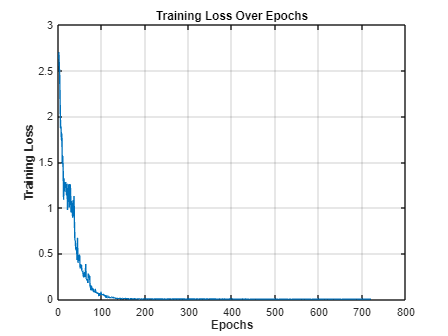


% Plot training loss
plot(info.TrainingLoss);
xlabel('Epochs', 'FontWeight', 'bold');
ylabel('Training Loss', 'FontWeight', 'bold');
title('Training Loss Over Epochs', 'FontWeight', 'bold');
grid on;

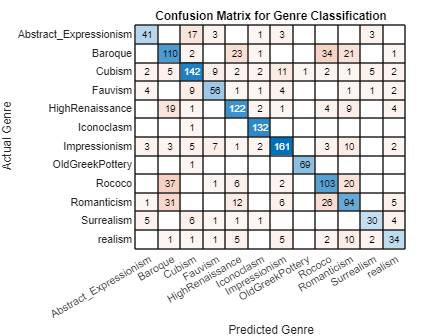

%correctly labelled
% Get the labels from the original imageDatastore
genreActual = genreTest.Labels;

% Proceed with your classification and evaluation
GenrePreds = classify(GenreNet, resizeTestImgs);
numCorrect = nnz(GenrePreds == genreActual);
fracCorrect = numCorrect / numel(GenrePreds);

confusionchart(genreActual, GenrePreds);
title('Confusion Matrix for Genre Classification');
xlabel('Predicted Genre');
ylabel('Actual Genre');

misclassified images

% Identify misclassified images
misclassifiedIndices = find(GenrePreds ~= genreActual);  % Get indices of misclassifications

% Create a table for misclassified images
misclassifiedImages = genreTest.Files(misclassifiedIndices);  % Get image file names
trueClasses = genreActual(misclassifiedIndices);               % Get true classes
predictedClasses = GenrePreds(misclassifiedIndices);          % Get predicted classes

% Create a table
misclassificationTable = table(misclassifiedImages, trueClasses, predictedClasses, ...
    'VariableNames', {'ImageName', 'TrueClass', 'PredictedClass'});

% Display the table
disp(misclassificationTable);

                                                                                    ImageName                                                                                           TrueClass               PredictedClass    
    __________________________________________________________________________________________________________________________________________________________________________    ______________________    ______________________

    {'D:\git\FYP\Python\TwoStage\data\Pandora7k\Abstract_Expressionism\76_2553_152_ph_web.png'                                                                               }    Abstract_Expressionism    Cubism                
    {'D:\git\FYP\Python\TwoStage\data\Pandora7k\Abstract_Expressionism\Ernst_Ludwig_Kirchner___Tutt_Art___18_.png'                                                           }    Abstract_Expressionism    Cubism      


% Optionally, save the table to a CSV file
writetable(misclassificationTable, 'misclassificationsResent50Orginal.csv');

percentage of each class taht is accurate

% Get unique class labels
classLabels = unique(genreActual);

% Calculate the confusion matrix
confusionMat = confusionmat(genreActual, GenrePreds);

% Calculate correct classification percentages directly
correctPercentage = diag(confusionMat) ./ sum(confusionMat, 2) * 100;

% Create a table for better visualization
percentageTable = table(classLabels, correctPercentage, ...
    'VariableNames', {'ClassLabel', 'CorrectPercentage'});

% Handle any potential division by zero
percentageTable.CorrectPercentage(isnan(percentageTable.CorrectPercentage)) = 0;

% Display the percentages

new code 

% Calculate Accuracy
accuracy = sum(diag(confusionMat)) / sum(confusionMat(:));
disp(['Accuracy: ' num2str(accuracy)]);

Accuracy: 0.71131



% Calculate Precision, Recall, and F1 Score for each class
numClasses = size(confusionMat, 1);
precision = zeros(1, numClasses);
recall = zeros(1, numClasses);
f1Score = zeros(1, numClasses);

for i = 1:numClasses
    % True Positives (TP), False Positives (FP), False Negatives (FN)
    TP = confusionMat(i, i);
    FP = sum(confusionMat(:, i)) - TP;
    FN = sum(confusionMat(i, :)) - TP;
    
    % Precision = TP / (TP + FP)
    precision(i) = TP / (TP + FP);
    
    % Recall = TP / (TP + FN)
    recall(i) = TP / (TP + FN);
    
    % F1 Score = 2 * (Precision * Recall) / (Precision + Recall)
    f1Score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end

% Display Precision, Recall, and F1 Score for each class
disp('Precision for each class:');

Precision for each class:


disp(precision);

    0.7321    0.5340    0.7676    0.7179    0.7052    0.9296    0.8342    0.9857    0.5920    0.5663    0.7317    0.6296




disp('Recall for each class:');

Recall for each class:


disp(recall);

    0.6029    0.5729    0.7717    0.7089    0.7531    0.9925    0.8173    0.9857    0.6095    0.5371    0.6250    0.5574




disp('F1 Score for each class:');

F1 Score for each class:


disp(f1Score);

    0.6613    0.5528    0.7696    0.7134    0.7284    0.9600    0.8256    0.9857    0.6006    0.5513    0.6742    0.5913




% Optionally, save the metrics into a table for better visualization
metricsTable = table(classLabels, precision', recall', f1Score', ...
    'VariableNames', {'ClassLabel', 'Precision', 'Recall', 'F1Score'});

disp(metricsTable);

          ClassLabel          Precision    Recall     F1Score
    ______________________    _________    _______    _______

    Abstract_Expressionism     0.73214     0.60294    0.66129
    Baroque                    0.53398     0.57292    0.55276
    Cubism                     0.76757     0.77174    0.76965
    Fauvism                    0.71795     0.70886    0.71338
    HighRenaissance             0.7052     0.75309    0.72836
    Iconoclasm                 0.92958     0.99248       0.96
    Impressionism               0.8342     0.81726    0.82564
    OldGreekPottery            0.98571     0.98571    0.98571
    Rococo                     0.59195     0.60947    0.60058
    Romanticism                0.56627     0.53714    0.55132
    Surrealism                 0.73171       0.625    0.67416
    realism                    0.62963     0.55738     0.


% Save metrics to CSV
%writetable(metricsTable, 'classificationMetrics.csv');


% Dynamic sheet name based on current date
sheetName = ['Metrics_original'];

% Save metrics to a specific sheet in an Excel file
filename = 'classificationMetrics.xlsx';  % Name of the Excel file

% Write the table to the Excel file in the specified sheet
writetable(metricsTable, filename, 'Sheet', sheetName);

disp(['Metrics saved to sheet: ' sheetName ' in file: ' filename]);

Metrics saved to sheet: Metrics_original in file: classificationMetrics.xlsx
